# 需求分析：区域生长确定目标区域

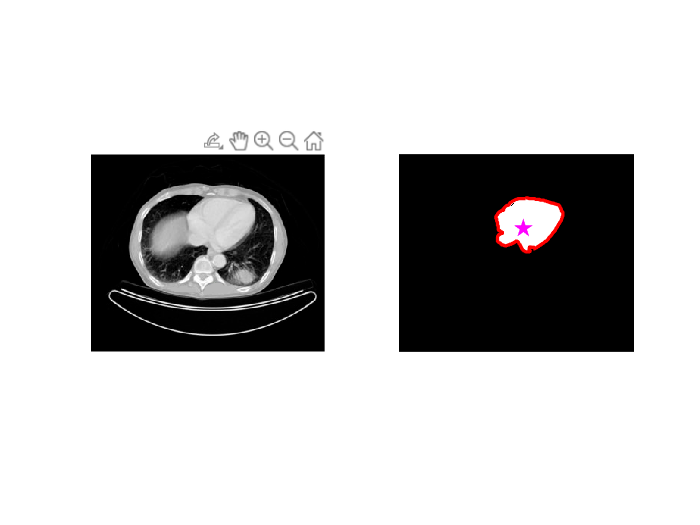

clear;clc;
img = imread('test.bmp');
subplot(1, 2, 1)
imshow(img);
% RGB 图转灰度图
if length(size(img)) > 2
    I = rgb2gray(img); 
else
    I = img;
end
% 转成浮点数格式
I = double(I);
% 设置种子点
p1 = ginput(1);
x = round(p1(2));
y = round(p1(1));
% 阈值
threshold = 20;
% 获取 ROI
J = RegionGrowing(I, [x, y], threshold);
% 根据 ROI 确定边界
[bound, F] = RegionBoundary(J);
subplot(1, 2, 2)
imshow(J)
hold on 
plot(y, x, 'pm', 'MarkerSize', 10, 'MarkerFaceColor', 'm')
plot(bound(:, 1), bound(:, 2), 'r', 'LineWidth', 2)
hold off